addpath('C:\Users\Bergles Lab\Documents\MATLAB\MATLAB\OldRoutines\findICpeaks.m'); %add Matlab path to find peaks

## Wildtype Animals

%converted to 16bit and dFoF
wt_paths = {'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-265-P7_Wildtype_PCA\ICinfo16_dFoF.mat';
            'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-314-P6_Wildtype_PCA\ICinfo16_dFoF.mat';
            'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-330_processed\ICinfo16_dFoF.mat';
            'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-337-ds_PCApro\ICinfo16_dFoF.mat';
            'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-342_P2ry1het_ds.tif_PCA\ICinfo16_dFoF.mat';
            'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-495-P7-Snap25GC6s_Wildtype_PCA\ICinfo16_dFoF.mat';
            'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-569_P6-Snap25GC6s_PCA\ICinfo16_dFoF.mat';
            'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\DUP_Experiment-571_P6-Snap25GC6s_PCA\ICinfo16_dFoF.mat';
            'M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\Experiment-974_Snap25GC6s_vGluT3het\ICinfo16_dFoF.mat'
            };
[WT_stats] = groupData(wt_paths,16);
%export_fig 'C:\Users\Bergles Lab\Desktop\temp\Eps figs\Figure3\WTgroup.eps'

%save('M:\Bergles Lab Data\Projects\In vivo imaging\WILDTYPE\WT_stats.mat','WT_stats');

%%for figure, exp 569, between 330 and 390s
% left_time = 330;
% right_time = 390;
% load(wt_paths{7});
% lt_org = [255, 166 , 38]/255;
% dk_org = [255, 120, 0]/255;
% lt_blue = [50, 175, 242]/255;
% dk_blue = [0, 13, 242]/255;
% 
% [m,n] = size(ICsignal);
% T = ([1:1:m]/10)';
% figure;
% plot(T,smooth(ICsignal(:,1)),'Color',lt_org);
% hold on;
% plot(T,smooth(ICsignal(:,2)),'Color',lt_blue);
% xlim([left_time, right_time]);
% %scatter(LICinfo(:,2)/10,LICinfo(:,1),20,dk_org,'filled','o');
% %scatter(RICinfo(:,2)/10,RICinfo(:,1),20,dk_blue,'filled','o');
% 
% scatter(pkData((pkData(:,7)==2),3)/10,pkData((pkData(:,7)==2),4),pkData(pkData(:,7)==2,5)*200,dk_blue,'MarkerFaceColor', dk_blue);
% scatter(pkData((pkData(:,7)==1),1)/10,pkData((pkData(:,7)==1),2),pkData(pkData(:,7)==1,5)*200,dk_org,'MarkerFaceColor', dk_org);
% 



## Right ablations

%converted to 16bit and dFoF
rabl_paths = {'M:\Bergles Lab Data\Projects\In vivo imaging\Unilateral Ablations\Right Ablations\DUP_Experiment-373_processed\ICinfo16_dFoF.mat';
              % very weak signal 'M:\Bergles Lab Data\Projects\In vivo imaging\Unilateral Ablations\Right Ablations\DUP_Experiment-375-Rabl_ds.tif_PCA\ICinfo_PCA.mat';
              'M:\Bergles Lab Data\Projects\In vivo imaging\Unilateral Ablations\Right Ablations\DUP_Experiment-378_ds.tif_PCA\ICinfo16_dFoF.mat';
              'M:\Bergles Lab Data\Projects\In vivo imaging\Unilateral Ablations\Right Ablations\DUP_Experiment-385_dstif.tif_PCA\ICinfo16_dFoF.mat';
              'M:\Bergles Lab Data\Projects\In vivo imaging\Unilateral Ablations\Right Ablations\DUP_Experiment-387_Rabl_ds.tif_PCA\ICinfo16_dFoF.mat';
              'M:\Bergles Lab Data\Projects\In vivo imaging\Unilateral Ablations\Right Ablations\DUP_Experiment-648_Rabl\ICinfo16_dFoF.mat'};
              [rabl_stats] = groupData(rabl_paths,16);
export_fig 'C:\Users\Bergles Lab\Desktop\temp\Eps figs\Figure3\Rablgroup.eps'
save('M:\Bergles Lab Data\Projects\In vivo imaging\Unilateral Ablations\Right Ablations\rabl_stats.mat','rabl_stats');

              

## Left ablations

%converted to 16bit and dFoF
labl_paths = {'M:\Bergles Lab Data\Projects\In vivo imaging\Unilateral Ablations\Left Ablations\DUP_Experiment-320_processed\ICinfo16_dFoF.mat';
               'M:\Bergles Lab Data\Projects\In vivo imaging\Unilateral Ablations\Left Ablations\DUP_Experiment-321_processed\ICinfo16_dFoF.mat';
               'M:\Bergles Lab Data\Projects\In vivo imaging\Unilateral Ablations\Left Ablations\DUP_Experiment-323_processed\ICinfo16_dFoF.mat';
               'M:\Bergles Lab Data\Projects\In vivo imaging\Unilateral Ablations\Left Ablations\DUP_Experiment-325_processed\ICinfo16_dFoF.mat';
               'M:\Bergles Lab Data\Projects\In vivo imaging\Unilateral Ablations\Left Ablations\DUP_Experiment-336_processed\ICinfo16_dFoF.mat'};
           
[labl_stats] = groupData(labl_paths,16);
export_fig 'C:\Users\Bergles Lab\Desktop\temp\Eps figs\Figure3\Lablgroup.eps'
save('M:\Bergles Lab Data\Projects\In vivo imaging\Unilateral Ablations\Left Ablations\labl_stats.mat','labl_stats');
%[labl_statsLR = analGroupDataLR()


## Cortex Ablations

paths = loadFileList('.\Data\Cortical Ablations\*\*ICinfo16_dFoF.mat');
                
                [ctxabl_stats] = groupData(paths,16);

                %save group data
                [pathstr, name, ext] =  fileparts(paths{1});
                parts = strsplit(pathstr,'\');
                pathstr = strjoin(parts(1:end-1),'\');
                save([pathstr '\groupStats.mat'], 'ctxabl_stats');


## NBQX

NBQX_paths = {'M:\Bergles Lab Data\Projects\In vivo imaging\NBQX to RWM\Intact RWM\DUP_Experiment-442_P7_Snap25GC6s_NBQXtoIntactRWM_PCA\ICinfo16_dFoF.mat';
              'M:\Bergles Lab Data\Projects\In vivo imaging\NBQX to RWM\Puncture RWM\DUP_Experiment-430_P7_Snap25GC6s_NBQX_PCA\ICinfo16_dFoF.mat';
              'M:\Bergles Lab Data\Projects\In vivo imaging\NBQX to RWM\Puncture RWM\DUP_Experiment-468_Snap25GC6s_NBQXtoRWM_PCA\ICinfo16_dFoF.mat';
              'M:\Bergles Lab Data\Projects\In vivo imaging\NBQX to RWM\Puncture RWM\DUP_Experiment-613_P7_Snap25GC6s_vGluT3het_NBQX_L_PCA\ICinfo16_dFoF.mat';
              'M:\Bergles Lab Data\Projects\In vivo imaging\NBQX to RWM\Puncture RWM\DUP_Experiment-650_Snap25GC6s_NBQX_PCA\ICinfo16_dFoF.mat'              
    };
        export_fig 'C:\Users\Bergles Lab\Desktop\temp\Eps figs\Figure3\NBQXgroup.eps'
          [NBQX_stats] = groupData(NBQX_paths,16); 
       save('M:\Bergles Lab Data\Projects\In vivo imaging\NBQX to RWM\NBQX_stats.mat','NBQX_stats');
          

## vGluT3 KO

vg3_paths = {'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\DUP_Experiment-496-P7-Snap25GC6s_vGluT3_PCA\ICinfo16_dFoF.mat';
             'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\DUP_Experiment-545_P8_Snap25GC6s_vGluT3_matreg_PCA\ICinfo16_dFoF.mat';
             'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\DUP_Experiment-593-Snap25GC6s_vGluT3KO_PCA\ICinfo16_dFoF.mat';
             'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\DUP_Experiment-606_Snap25GC6s_vGluT3KO_PCA\ICinfo16_dFoF.mat';
             'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\DUP_Experiment-607_Snap25GC6s_vGluT3KO_PCA\ICinfo16_dFoF.mat';
             'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\DUP_Experiment-799_Snap25GC6s_vGluT3KO_reg\ICinfo16_dFoF.mat';
             'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO\Experiment-974_Snap25GC6s_vGluT3KO\ICinfo16_dFoF.mat'};
             [vg3_stats] = groupData(vg3_paths,16); 
  

## vGluT3 KO bilateral abaltion

vg3abl_paths = {'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO ablation\Bilateral\DUP_Experiment-671_Snap25GC6s_vGluT3KO_bilat_abl_reg_PCA\ICinfo16_dFoF.mat';
                'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO ablation\Bilateral\DUP_Experiment-673_Snap25GC6s_vGluT3KO_bilat_abl_reg_PCA\ICinfo16_dFoF.mat';
                'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO ablation\Bilateral\DUP_Experiment-714_Snap25GC6s_vGluT3KO_bilateralablation_PCA\ICinfo16_dFoF.mat';
                %'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO ablation\Bilateral\DUP_Experiment-762_Snap25GC6s_vGluT3KO_bilateral_ablation_PCA\ICinfo16_dFoF.mat';
                'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO ablation\Bilateral\DUP_Experiment-763_Snap25GC6s_vGluT3KO_bilateral_ablation_PCA\ICinfo16_dFoF.mat';
                'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO ablation\Bilateral\DUP_Experiment-839_Snap25GC6s_vGluT3KO_bilabl\ICinfo16_dFoF.mat';
                'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO ablation\Bilateral\Experiment-840_Snap25GC6s_vGluT3KO_bilabl\ICinfo16_dFoF.mat';
                'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO ablation\Bilateral\Experiment-1347_Snap25GC6s_vGluT3KO_bilabl\ICinfo16_dFoF.mat';
               };
               %%updated top ROI to stretch across
                [vg3bil_stats] = groupData(vg3abl_paths,16); 

## vGluT3KO NBQX

binLim =          0    0.0200    0.0700    0.1200    0.1700    0.2200    0.2700    0.3200  100.0000


M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO NBQX\DUP_Experiment-610_P7_Snap25GC6s_vGluT3KO_NBQX_PCA\ICinfo16_dFoF.mat


Rdom = 41

width = 13.0514

tempPkData =    1.0e+03 *

    0.0310    0.0003    0.0310    0.0002    0.0001    0.0010    0.0010
    0.2380    0.0001    0.2390    0.0001    0.0000    0.0010    0.0010
    0.3070    0.0000    0.3070    0.0000    0.0000    0.0010    0.0010
    0.3260    0.0000    0.3260    0.0000    0.0000    0.0020    0.0010
    0.5650    0.0000    0.5650    0.0000    0.0000    0.0010    0.0010
    0.6720    0.0002    0.6710    0.0002    0.0000    0.0010    0.0010
    0.7000    0.0001    0.7000    0.0000    0.0000    0.0020    0.0010
    0.7440    0.0001    0.7420    0.0000    0.0000    0.0010    0.0010
    1.2680    0.0001    1.2680    0.0001    0.0000    0.0010    0.0010
    1.3270    0.0001    1.3270    0.0000    0.0000    0.0010    0.0010


LIC: 80 peaks total, 59 corresponding RIC peaks.
RIC: 76 peaks total, 59 corresponding LIC peaks.
Mean RIC amplitude: 0.091228
Mean LIC amplitude: 0.10099
M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO NBQX\DUP_Experiment-610_P7_Snap25GC6s_vGluT3KO_NBQX_PCA\ICinfo16_dFoF
M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO NBQX\DUP_Experiment-800_Snap25GC6s_vGluT3KO_NBQX_reg\ICinfo16_dFoF.mat


Rdom = 64

width = 13.1054

tempPkData =    15.0000    0.0349   15.0000    0.0288    0.0061    1.0000    1.0000
   70.0000    0.1019   69.0000    0.0991    0.0027    1.0000    1.0000
  254.0000    0.2047  254.0000    0.1903    0.0144    1.0000    1.0000
  292.0000    0.1694  291.0000    0.1422    0.0272    1.0000    1.0000
  410.0000    0.0909  410.0000    0.0903    0.0006    1.0000    1.0000
  598.0000    0.0500  598.0000    0.0310    0.0190    1.0000    1.0000
  627.0000    0.0777  627.0000    0.0428    0.0349    1.0000    1.0000
  639.0000    0.0710  640.0000    0.0614    0.0096    1.0000    1.0000
  719.0000    0.0180  719.0000    0.0010    0.0171    2.0000    1.0000
  750.0000    0.0435  750.0000    0.0406    0.0030    1.0000    1.0000


LIC: 94 peaks total, 81 corresponding RIC peaks.
RIC: 104 peaks total, 81 corresponding LIC peaks.
Mean RIC amplitude: 0.12186
Mean LIC amplitude: 0.11914
M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO NBQX\DUP_Experiment-800_Snap25GC6s_vGluT3KO_NBQX_reg\ICinfo16_dFoF
M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO NBQX\Experiment-872_Snap25GC6s_vGluT3KO_NBQX\ICinfo16_dFoF.mat


Rdom = 55

width = 10.2011

tempPkData =    1.0e+03 *

    0.1130    0.0003    0.1110    0.0002    0.0001    0.0010    0.0010
    0.1330    0.0003    0.1360    0.0002    0.0001    0.0010    0.0010
    0.3270    0.0000    0.3270    0.0000    0.0000    0.0010    0.0010
    0.6750    0.0001    0.6750    0.0001    0.0000    0.0010    0.0010
    0.8200    0.0001    0.8200    0.0001    0.0000    0.0020    0.0010
    0.8630    0.0002    0.8630    0.0001    0.0001    0.0020    0.0010
    1.0460    0.0001    1.0460    0.0001    0.0001    0.0020    0.0010
    1.1620    0.0000    1.1620   -0.0000    0.0000    0.0020    0.0010
    1.4620    0.0000    1.4620    0.0000    0.0000    0.0020    0.0010
    1.5660    0.0000    1.5660    0.0000    0.0000    0.0010    0.0010


LIC: 89 peaks total, 66 corresponding RIC peaks.
RIC: 88 peaks total, 66 corresponding LIC peaks.
Mean RIC amplitude: 0.10604
Mean LIC amplitude: 0.11169
M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO NBQX\Experiment-872_Snap25GC6s_vGluT3KO_NBQX\ICinfo16_dFoF
M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO NBQX\Experiment-873_Snap25GC6s_vGluT3KO_NBQX_Lear\ICinfo16_dFoF.mat


Rdom = 57

width = 11.0155

tempPkData =    88.0000    0.0369   88.0000    0.0137    0.0232    2.0000    1.0000
  396.0000    0.1068  396.0000    0.0957    0.0111    1.0000    1.0000
  439.0000    0.1948  439.0000    0.0967    0.0981    2.0000    1.0000
  571.0000    0.1458  571.0000    0.1295    0.0163    2.0000    1.0000
  604.0000    0.0531  605.0000    0.0508    0.0024    1.0000    1.0000
  652.0000    0.0687  653.0000    0.0529    0.0158    1.0000    1.0000
  688.0000    0.2515  688.0000    0.1324    0.1191    1.0000    1.0000
  704.0000    0.1511  704.0000    0.0717    0.0794    2.0000    1.0000
  732.0000    0.3678  731.0000    0.3113    0.0565    1.0000    1.0000
  752.0000    0.2985  752.0000    0.1626    0.1359    2.0000    1.0000


LIC: 117 peaks total, 91 corresponding RIC peaks.
RIC: 102 peaks total, 91 corresponding LIC peaks.
Mean RIC amplitude: 0.13112
Mean LIC amplitude: 0.12999
M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO NBQX\Experiment-873_Snap25GC6s_vGluT3KO_NBQX_Lear\ICinfo16_dFoF
M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO NBQX\Experiment-973_Snap25GC6s_vGluT3KO_NBQX_lear\ICinfo16_dFoF.mat


Rdom = 60

width = 12.1524

tempPkData =   111.0000    0.0618  111.0000    0.0537    0.0080    1.0000    1.0000
  245.0000    0.2510  245.0000    0.1822    0.0688    1.0000    1.0000
  294.0000    0.0418  294.0000    0.0264    0.0154    1.0000    1.0000
  320.0000    0.0309  320.0000    0.0145    0.0164    2.0000    1.0000
  413.0000    0.0901  413.0000    0.0426    0.0474    1.0000    1.0000
  483.0000    0.0943  483.0000    0.0535    0.0408    2.0000    1.0000
  537.0000    0.0913  537.0000    0.0706    0.0206    1.0000    1.0000
  552.0000    0.0757  552.0000    0.0716    0.0041    3.0000    1.0000
  572.0000    0.2507  576.0000    0.2504    0.0003    1.0000    1.0000
  783.0000    0.2242  782.0000    0.1908    0.0334    1.0000    1.0000


LIC: 100 peaks total, 80 corresponding RIC peaks.
RIC: 99 peaks total, 80 corresponding LIC peaks.
Mean RIC amplitude: 0.10048
Mean LIC amplitude: 0.097597
M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO NBQX\Experiment-973_Snap25GC6s_vGluT3KO_NBQX_lear\ICinfo16_dFoF
delta


delta =     0.7677    0.7876    0.7353    0.6915    0.7679


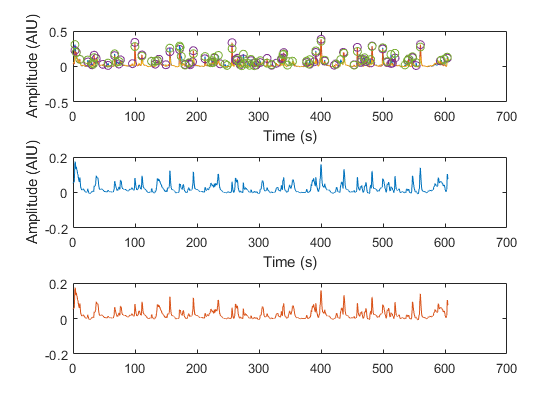

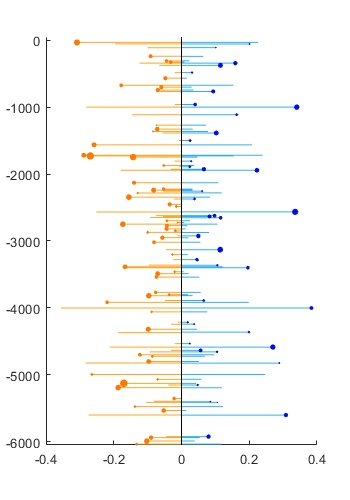

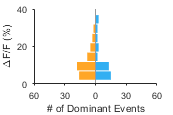

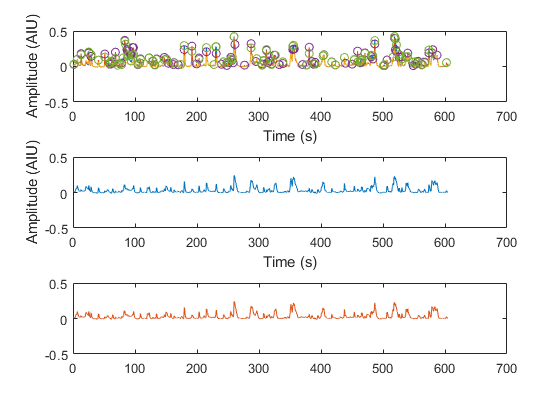

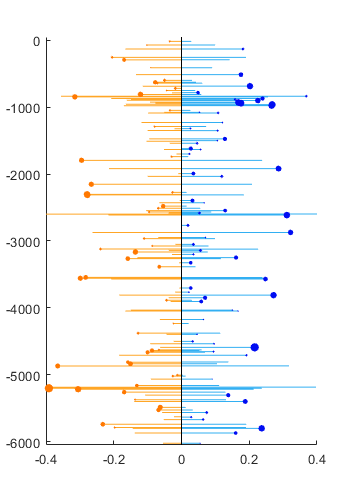

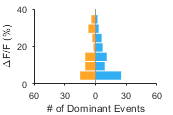

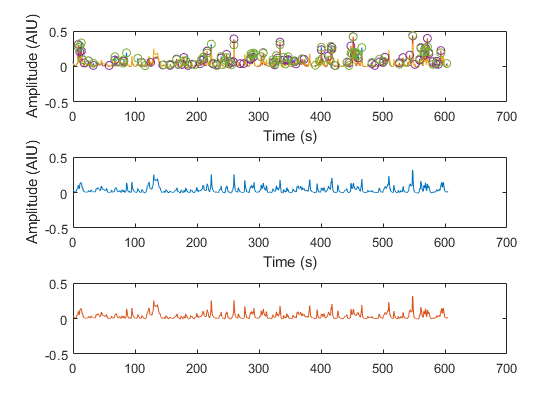

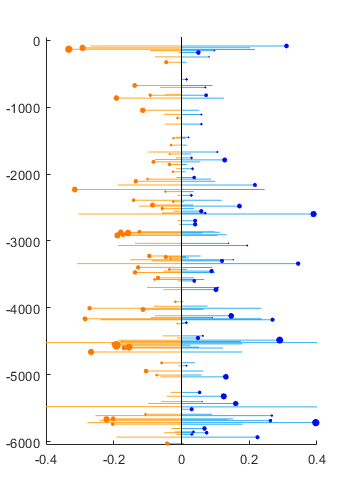

vg3NBQX_paths = {'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO NBQX\DUP_Experiment-610_P7_Snap25GC6s_vGluT3KO_NBQX_PCA\ICinfo16_dFoF.mat';
                'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO NBQX\DUP_Experiment-800_Snap25GC6s_vGluT3KO_NBQX_reg\ICinfo16_dFoF.mat';
                'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO NBQX\Experiment-872_Snap25GC6s_vGluT3KO_NBQX\ICinfo16_dFoF.mat';
                'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO NBQX\Experiment-873_Snap25GC6s_vGluT3KO_NBQX_Lear\ICinfo16_dFoF.mat';
                'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO NBQX\Experiment-973_Snap25GC6s_vGluT3KO_NBQX_lear\ICinfo16_dFoF.mat'
                };
                [statsvg3NBQX] = groupData(vg3NBQX_paths,16);

## vGlut3 BBE

vg3BBE_paths = {'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO BBE\Drug\1248\ICinfo16_dFoF.mat';
                'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO BBE\Drug\1250\ICinfo16_dFoF.mat';
                'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO BBE\Drug\1255\ICinfo16_dFoF.mat';
                'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO BBE\Drug\1263\ICinfo16_dFoF.mat';
                'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO BBE\Drug\1329\ICinfo16_dFoF.mat';
                };
    [statsBBE] = groupData(vg3BBE_paths,16);  
    


## vglut3 sham bilateral

vg3sham_paths = {'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO BBE\Sham\1254\ICinfo16_dFoF.mat';
                 'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO BBE\Sham\1251\ICinfo16_dFoF.mat';
                 'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO BBE\Sham\1261\ICinfo16_dFoF.mat';
                 'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO BBE\Sham\1326\ICinfo16_dFoF.mat';
    };

[statsSham] = groupData(vg3sham_paths,16);

    

## vGluT3 unilateral ablation

vg3UNIabl_paths = {'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO ablation\Unilateral\DUP_Experiment-633_Snap25GC6s_vGlut3KO_Labl_PCA\ICinfo16_dFoF.mat';
    'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO ablation\Unilateral\Experiment-992-Snap25GC6s_vGluT3KO_L_abl\ICinfo16_dFoF.mat';
    'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO ablation\Unilateral\Experiment-1004-Snap25GC6s_vGluT3KO_L_abl\ICinfo16_dFoF.mat'};          
                [stats] = groupData(vg3UNIabl_paths,16);         

## VGLUT3 CN ablation

vg3CNablation = {'M:\Bergles Lab Data\Projects\In vivo imaging\vGluT3 KO CN ablation\Experiment-977_Snap25GC6s_vGluT3KO_L_CNabl\ICinfo16_dFoF.mat';
    };

[stats] = groupData(vg3CNablation,16); 

## Bilateral WT ablations

%%updated top ROI to stretch across
bilatablWT_paths = {'M:\Bergles Lab Data\Projects\In vivo imaging\Bilateral Ablations\DUP_Experiment-640_Snap25GC6s_bilateral_abl_reg_PCA\ICinfo16_dFoF.mat';
                    'M:\Bergles Lab Data\Projects\In vivo imaging\Bilateral Ablations\DUP_Experiment-641_Snap25GC6s_bilateral_abl_reg_PCA\ICinfo16_dFoF.mat'
                    'M:\Bergles Lab Data\Projects\In vivo imaging\Bilateral Ablations\DUP_Experiment-642_Snap25GC6s_bilateral_abl_PCA\ICinfo16_dFoF.mat';
                    'M:\Bergles Lab Data\Projects\In vivo imaging\Bilateral Ablations\DUP_Experiment-643_Snap25GC6s_bilateral_abl_PCA\ICinfo16_dFoF.mat';
                    'M:\Bergles Lab Data\Projects\In vivo imaging\Bilateral Ablations\DUP_Experiment-644_Snap25GC6s_bilateral_abl_PCA\ICinfo16_dFoF.mat'
    };
[bilabl_stats] = groupData(bilatablWT_paths,16);
export_fig 'C:\Users\Bergles Lab\Desktop\temp\Eps figs\Figure3\bilablgroup.eps'
save('M:\Bergles Lab Data\Projects\In vivo imaging\Bilateral Ablations\bilabl_stats.mat','bilabl_stats');


## Bilateral Mannitol Sham

bilSham_paths = {'M:\Bergles Lab Data\Projects\In vivo imaging\Bilateral Mannitol Sham\DUP_Experiment-594-Snap25GC6s_mannitol_sham_bilat_PCA\ICinfo16_dFoF.mat';
                 'M:\Bergles Lab Data\Projects\In vivo imaging\Bilateral Mannitol Sham\DUP_Experiment-602_Snap25GC6s_mannitol_sham_bilat_PCA\ICinfo16_dFoF.mat';
                 'M:\Bergles Lab Data\Projects\In vivo imaging\Bilateral Mannitol Sham\DUP_Experiment-620_Snap25GC6s_mannitolsham_bilat_PCA\ICinfo16_dFoF.mat';
                 'M:\Bergles Lab Data\Projects\In vivo imaging\Bilateral Mannitol Sham\DUP_Experiment-625_Snap25GC6s_mannitolsham_bilat_2_355_PCA\ICinfo16_dFoF.mat';
                 'M:\Bergles Lab Data\Projects\In vivo imaging\Bilateral Mannitol Sham\Experiment-857_Snap25GC6s_mannitol_sham_bilat\ICinfo16_dFoF.mat'
    };

[shamBil_stats] = groupData(bilSham_paths ,16);

## Bilateral MRS2500

bilMRS_paths = {'M:\Bergles Lab Data\Projects\In vivo imaging\MRS2500 to RWM\DUP_Experiment-592_P7_Snap25GC6s_MRS2500double_PCA\ICinfo16_dFoF.mat';
                'M:\Bergles Lab Data\Projects\In vivo imaging\MRS2500 to RWM\DUP_Experiment-601_Snap25GC6s_MRS2500_bilat_PCA\ICinfo16_dFoF.mat';
                'M:\Bergles Lab Data\Projects\In vivo imaging\MRS2500 to RWM\DUP_Experiment-619_Snap25GC6s_MRS2500_bilat_PCA\ICinfo16_dFoF.mat';
                'M:\Bergles Lab Data\Projects\In vivo imaging\MRS2500 to RWM\DUP_Experiment-623_Snap25GC6s_MRS2500_bilat_PCA\ICinfo16_dFoF.mat';
                'M:\Bergles Lab Data\Projects\In vivo imaging\MRS2500 to RWM\DUP_Experiment-626_Snap25GC6s_MRS2500_bilat_PCA\ICinfo16_dFoF.mat'
                'M:\Bergles Lab Data\Projects\In vivo imaging\MRS2500 to RWM\Experiment-852_Snap25GC6s_MRS2500bilateral\ICinfo16_dFoF.mat';

    };

[bilMRS_stats] = groupData(bilMRS_paths,16);

## P2ry1 KO

P2ry1KO_paths = {'M:\Bergles Lab Data\Projects\In vivo imaging\P2ry1 KO\DUP_Experiment-338_processed\ICinfo16_dFoF.mat';
                 'M:\Bergles Lab Data\Projects\In vivo imaging\P2ry1 KO\DUP_Experiment-344_ds.tif_PCA\ICinfo16_dFoF.mat';
                 'M:\Bergles Lab Data\Projects\In vivo imaging\P2ry1 KO\DUP_Experiment-354-P7-Snap25GC6s_P2ry1KO.tif_PCA\ICinfo16_dFoF.mat';
                 'M:\Bergles Lab Data\Projects\In vivo imaging\P2ry1 KO\DUP_Experiment-360_ds.tif_PCA\ICinfo16_dFoF.mat';
                 'M:\Bergles Lab Data\Projects\In vivo imaging\P2ry1 KO\DUP_Experiment-361_ds.tif_PCA\ICinfo16_dFoF.mat';
                 'M:\Bergles Lab Data\Projects\In vivo imaging\P2ry1 KO\DUP_Experiment-591_P7_Snap25GC6s_P2ry1KO_PCA\ICinfo16_dFoF.mat';
                 'M:\Bergles Lab Data\Projects\In vivo imaging\P2ry1 KO\DUP_Experiment-805\ICinfo16_dFoF.mat';
                 };
             
              [bilMRS_stats] = groupData(P2ry1KO_paths,16);   

## TMIE KO

TMIE_paths = {'M:\Bergles Lab Data\Projects\In vivo imaging\TMIE KO\Experiment-1288\ICinfo16_dFoF.mat';
              'M:\Bergles Lab Data\Projects\In vivo imaging\TMIE KO\Experiment-1334\ICinfo16_dFoF.mat';
              'M:\Bergles Lab Data\Projects\In vivo imaging\TMIE KO\Experiment-1368\ICinfo16_dFoF.mat';
              'M:\Bergles Lab Data\Projects\In vivo imaging\TMIE KO\Experiment-1450\ICinfo16_dFoF.mat';
              }
TMIEstat = groupData(TMIE_paths,16);

TMIE_littermate = {'M:\Bergles Lab Data\Projects\In vivo imaging\TMIE WT Littermate\Experiment-1333\ICinfo16_dFoF.mat';
                   'M:\Bergles Lab Data\Projects\In vivo imaging\TMIE WT Littermate\Experiment-1371\ICinfo16_dFoF.mat';
                   'M:\Bergles Lab Data\Projects\In vivo imaging\TMIE WT Littermate\Experiment-1449\ICinfo16_dFoF.mat';
                   'M:\Bergles Lab Data\Projects\In vivo imaging\TMIE WT Littermate\Experiment-1451\ICinfo16_dFoF.mat'
                  };
              
TMIEWTstat= groupData(TMIE_littermate,16);


[avgVg3bil, sevg3bil, hwvg3bil, amplvg3bil] = waveform2(TMIE_paths);
[avgVg3, seVg3m, hwVg3, amplVg3] = waveform2(TMIE_littermate);

indStats = TMIEWTstat;
indStats2 = TMIEstat;
plotFlag = 1;
    m = size(indStats,1);
    m2 = size(indStats2,1);
    lgrey = [0.8 0.8 0.8];
    markSize = 2;
    meanMarkSize = 15;
    if(plotFlag)
        h = figure;
        h.Units = 'inches';
        h.Position = [5 5 6.5/2 1.4/1.5];
        %frequency
        subplot(1,3,1);
            mean1 = mean(indStats.Var7)/10;
            std1 = (std(indStats.Var7)/10)/sqrt(m);
            mean2 = mean(indStats2.Var7)/10;
            std2 = (std(indStats2.Var7)/10)/sqrt(m2);
            scatter(ones(m,1), indStats.Var7/10,markSize,lgrey,'filled');
            hold on;
            scatter(2*ones(m2,1),indStats2.Var7/10,markSize,lgrey,'filled');
            scatter(1,mean1,meanMarkSize,'k','filled');
            scatter(2,mean2,meanMarkSize,'r','filled');
            line([1 2; 1 2], [mean1+std1 mean2+std2; mean1-std1 mean2-std2],'Color','k');
            ylim([0,25]);
            yticks([0 12.5 25]);
            xlim([0 3]);
            %xticklabels({'',cond1,cond2,''});
            ylabel('Total Events Per Min');
            [h, p] = ttest2(indStats.Var7,indStats2.Var7);
            pt(1) = p;
            disp(p);
        %amplitude
        subplot(1,3,2);
            %indMean1 = mean([indStats.meanL indStats.meanR],2);
            %indMean2 = mean([indStats2.meanL indStats2.meanR],2);
            mean2 = mean(amplvg3bil);
            std2 = std(amplvg3bil)/sqrt(m);
            mean1 = mean(amplVg3);
            std1 = std(amplVg3)/sqrt(m2);
            scatter(ones(m,1),amplVg3,markSize,lgrey,'filled');
            hold on;
            scatter(2*ones(m2,1), amplvg3bil,markSize,lgrey,'filled');
            scatter(1,mean1,meanMarkSize,'k','filled');
            scatter(2,mean2,meanMarkSize,'r','filled');
            line([1 2; 1 2], [mean1+std1 mean2+std2; mean1-std1 mean2-std2],'Color','k');
            ylim([0,.2]);
            yticks([0 .1 .12 0.20]);
            xlim([0 3]);
            %xticklabels({'',cond1,cond2,''});
            ylabel('Amplitude (dFoF)');
            [h, p] = ttest2(amplVg3,amplvg3bil);
            pt(2)=p;
            disp(p);
       subplot(1,3,3);
            mean2 = mean(hwvg3bil)/10;
            std2 = std(hwvg3bil)/10/sqrt(m);
            mean1 = mean(hwVg3)/10;
            std1 = std(hwVg3)/10/sqrt(m2);
           scatter(ones(m,1), hwVg3/10,markSize,lgrey,'filled');
           hold on;
           scatter(2*ones(m2,1), hwvg3bil/10,markSize,lgrey,'filled')';
           scatter(1,mean1,meanMarkSize,'k','filled');
            scatter(2,mean2,meanMarkSize,'r','filled');
            line([1 2; 1 2], [mean1+std1 mean2+std2; mean1-std1 mean2-std2],'Color','k');
           ylim([0 1.5]);
           yticks([0 0.5 1 1.5]);
           xlim([0 3]);
           %xticklabels({'',cond1,cond2,''});
           ylabel('Half-width (s)');
           [h,p] = ttest2(hwvg3bil,hwVg3);
           pt(5) = p;
           disp(p);
           figQuality(gcf,gca,[2.9 1])
           %export_fig('C:\Users\Bergles Lab\Desktop\temp\Eps figs\Fig5_Stats.eps',gcf);
    end


## Compare VG3, BBE, BBE Sham

vg3_avg = mean(vg3_stats{:,:},1)/10;
vg3_std = std(vg3_stats{:,:},1)/10;
vg3BBE_avg = mean(statsBBE{:,:},1)/10;
vg3BBE_std = std(statsBBE{:,:},1)/10;
vg3sham_avg = mean(statsSham{:,:},1)/10;
vg3sham_std = std(statsSham{:,:},1)/10;

%pull leftdom and rightdom individual
vg3_dom = vg3_stats{:,8:9}';
vg3_n = size(vg3_dom,2);
vg3BBE_dom = statsBBE{:,8:9}';
vg3BBE_n = size(vg3BBE_dom,2);
vg3sham_dom = statsSham{:,8:9}';
vg3sham_n = size(vg3sham_dom,2);


mk_size = 30;
figure();
xlim([0 9]);
ylim([0 16]);
scatter([1 2], vg3_avg(:,8:9),mk_size,'k','filled');
hold on;
line([ones(1,vg3_n); 2*ones(1,vg3_n)],[vg3_dom(1,:)/10; vg3_dom(2,:)/10],'Color',[0.8 0.8 0.8]);
line([1 2], vg3_avg(:,8:9),'Color','k');
line([1 2; 1 2], [vg3_avg(1,8:9) + vg3_std(8:9); vg3_avg(1,8:9) - vg3_std(8:9)],'Color','k');

l_n = 3;
r_n = 4;
line([l_n*ones(1,vg3BBE_n); r_n*ones(1,vg3BBE_n)],[vg3BBE_dom(1,:)/10; vg3BBE_dom(2,:)/10],'Color',[0.8 0.8 0.8]);
line([l_n r_n], vg3BBE_avg(:,8:9),'Color','k');
line([l_n r_n; l_n r_n], [vg3BBE_avg(1,8:9) + vg3BBE_std(8:9); vg3BBE_avg(1,8:9) - vg3BBE_std(8:9)],'Color','k');
scatter([l_n r_n], vg3BBE_avg(:,8:9),mk_size,'k','filled');

l_n = 5;
r_n = 6;
line([l_n*ones(1,vg3sham_n); r_n*ones(1,vg3sham_n)],[vg3sham_dom(1,:)/10; vg3sham_dom(2,:)/10],'Color',[0.8 0.8 0.8]);
line([l_n r_n], vg3sham_avg(:,8:9),'Color','k');
line([l_n r_n; l_n r_n], [vg3sham_avg(1,8:9) + vg3sham_std(8:9); vg3sham_avg(1,8:9) - vg3sham_std(8:9)],'Color','k');
scatter([l_n r_n], vg3BBE_avg(:,8:9),mk_size,'k','filled');


             
             
             
             


%ANOVA tests
% WT_dom = WT_stats{:,8:9};
% WT_n = size(WT_dom,1);
% rabl_dom = rabl_stats{:,8:9};
% r_n = size(rabl_dom,1);
% labl_dom = labl_stats{:,8:9};
% l_n = size(labl_dom,1);
% bilabl_dom = bilabl_stats{:,8:9};
% b_n = size(bilabl_dom,1);
% 
% y = [WT_dom(:); rabl_dom(:); labl_dom(:); bilabl_dom(:)];
% g1 = [repmat({'left'},[WT_n, 1]); repmat({'right'},[WT_n, 1]);...
%       repmat({'left'},[r_n, 1]); repmat({'right'},[r_n, 1]);...
%       repmat({'left'},[l_n, 1]); repmat({'right'},[l_n, 1]);...
%       repmat({'left'},[b_n, 1]); repmat({'right'},[b_n, 1])];
% g2 = [repmat({'Control'},[WT_n*2, 1]); repmat({'L_abl'},[l_n*2, 1]);...
%       repmat({'R_abl'},[r_n*2, 1]); repmat({'bil_abl'},[b_n*2, 1])];
%   
% [p, tbl, stats] = anovan(y,{g1,g2},'model','interaction','varnames',{'g1','g2'});
% figure;
% results1 = multcompare(stats,'Dimension',[1 2])
% 
% WT_dom = WT_stats{:,1:2};
% WT_n = size(WT_dom,1);
% rabl_dom = rabl_stats{:,1:2};
% r_n = size(rabl_dom,1);
% labl_dom = labl_stats{:,1:2};
% l_n = size(labl_dom,1);
% bilabl_dom = bilabl_stats{:,1:2};
% b_n = size(bilabl_dom,1);
% 
% y = [WT_dom(:); rabl_dom(:); labl_dom(:); bilabl_dom(:)];
% g1 = [repmat({'left'},[WT_n, 1]); repmat({'right'},[WT_n, 1]);...
%       repmat({'left'},[r_n, 1]); repmat({'right'},[r_n, 1]);...
%       repmat({'left'},[l_n, 1]); repmat({'right'},[l_n, 1]);...
%       repmat({'left'},[b_n, 1]); repmat({'right'},[b_n, 1])];
% g2 = [repmat({'Control'},[WT_n*2, 1]); repmat({'L_abl'},[l_n*2, 1]);...
%       repmat({'R_abl'},[r_n*2, 1]); repmat({'bil_abl'},[b_n*2, 1])];
%   
% [p, tbl, stats] = anovan(y,{g1,g2},'model','interaction','varnames',{'g1','g2'});
% figure;
% results2 = multcompare(stats,'Dimension',[1 2])



## Compare MRS2500 and sham bilateral

WT_avg = mean(shamBil_stats{:,:},1)/10;
WT_std = std(shamBil_stats{:,:},1)/10;
rabl_avg = mean(bilMRS_stats{:,:},1)/10;
rabl_std = std(bilMRS_stats{:,:},1)/10;

%pull leftdom and rightdom individual
WT_dom = shamBil_stats{:,8:9}';
WT_n = size(WT_dom,2);
rabl_dom = bilMRS_stats{:,8:9}';
r_n = size(rabl_dom,2);

mk_size = 30;
figure;
xlim([0 9]);
ylim([0 16]);
scatter([1 2], WT_avg(:,8:9),mk_size,'k','filled');
hold on;
line([ones(1,WT_n); 2*ones(1,WT_n)],[WT_dom(1,:)/10; WT_dom(2,:)/10],'Color',[0.8 0.8 0.8]);
line([1 2], WT_avg(:,8:9),'Color','k');
line([1 2; 1 2], [WT_avg(1,8:9) + WT_std(8:9); WT_avg(1,8:9) - WT_std(8:9)],'Color','k','LineWidth',1);

line([3*ones(1,r_n); 4*ones(1,r_n)],[rabl_dom(1,:)/10; rabl_dom(2,:)/10],'Color',[0.8 0.8 0.8]);
line([3 4], rabl_avg(:,8:9),'Color','k');
line([3 4; 3 4], [rabl_avg(1,8:9) + rabl_std(8:9); rabl_avg(1,8:9) - rabl_std(8:9)],'Color','k','LineWidth',1);

scatter([3 4], rabl_avg(:,8:9),mk_size,'k','filled');
line([5*ones(1,l_n); 6*ones(1,l_n)],[labl_dom(1,:)/10; labl_dom(2,:)/10],'Color',[0.8 0.8 0.8]);
line([5 6], labl_avg(:,8:9),'Color','k');
line([5 6; 5 6], [labl_avg(1,8:9) + labl_std(8:9); labl_avg(1,8:9) - labl_std(8:9)],'Color','k','LineWidth',1);

scatter([5 6], labl_avg(:,8:9),mk_size,'k','filled');
line([7*ones(1,b_n); 8*ones(1,b_n)],[bilabl_dom(1,:)/10; bilabl_dom(2,:)/10],'Color',[0.8 0.8 0.8]);
line([7 8], bilabl_avg(:,8:9),'Color','k');
line([7 8; 7 8], [bilabl_avg(1,8:9) + bilabl_std(8:9); bilabl_avg(1,8:9) - bilabl_std(8:9)],'Color','k','LineWidth',1);
scatter([7 8], bilabl_avg(:,8:9),mk_size,'k','filled');

xlim([0.5 8.5]);
ylim([0 16]);
ylabel('Frequency of Dominant Events (events/min)');


## compare vGluT3KO to bilateral ablation

vg3_avg = mean(vg3_stats{:,:},1)/10;
vg3_std = std(vg3_stats{:,:},1)/10;
vg3bil_avg = mean(vg3bil_stats{:,:},1)/10;
vg3bil_std = std(vg3bil_stats{:,:},1)/10;
vg3NBQX_avg = mean(statsvg3NBQX{:,:},1)/10;
vg3NBQX_std = std(statsvg3NBQX{:,:},1)/10;
vg3BBE_avg = mean(statsBBE{:,:},1)/10;
vg3BBE_std = std(statsBBE{:,:},1)/10;

%pull leftdom and rightdom individual
vg3_dom = vg3_stats{:,8:9}';
vg3_n = size(vg3_dom,2);
vg3bil_dom = vg3bil_stats{:,8:9}';
vg3bil_n = size(vg3bil_dom,2);
vg3NBQX_dom = statsvg3NBQX{:,8:9}';
vg3NBQX_n = size(vg3NBQX_dom,2);
vg3BBE_dom = statsBBE{:,8:9}';
vg3BBE_n = size(vg3BBE_dom,2);

mk_size = 30;
figure();
xlim([0 9]);
ylim([0 16]);
scatter([1 2], vg3_avg(:,8:9),mk_size,'k','filled');
hold on;
line([ones(1,vg3_n); 2*ones(1,vg3_n)],[vg3_dom(1,:)/10; vg3_dom(2,:)/10],'Color',[0.8 0.8 0.8]);
line([1 2], vg3_avg(:,8:9),'Color','k');
line([1 2; 1 2], [vg3_avg(1,8:9) + vg3_std(8:9); vg3_avg(1,8:9) - vg3_std(8:9)],'Color','k');

line([3*ones(1,vg3bil_n); 4*ones(1,vg3bil_n)],[vg3bil_dom(1,:)/10; vg3bil_dom(2,:)/10],'Color',[0.8 0.8 0.8]);
line([3 4], vg3bil_avg(:,8:9),'Color','k');
line([3 4; 3 4], [vg3bil_avg(1,8:9) + vg3bil_std(8:9); vg3bil_avg(1,8:9) - vg3bil_std(8:9)],'Color','k');
scatter([3 4], vg3bil_avg(:,8:9),mk_size,'k','filled');

l_n = 5;
r_n = 6;
line([l_n*ones(1,vg3NBQX_n); r_n*ones(1,vg3NBQX_n)],[vg3NBQX_dom(1,:)/10; vg3NBQX_dom(2,:)/10],'Color',[0.8 0.8 0.8]);
line([l_n r_n], vg3NBQX_avg(:,8:9),'Color','k');
line([l_n r_n; l_n r_n], [vg3NBQX_avg(1,8:9) + vg3NBQX_std(8:9); vg3NBQX_avg(1,8:9) - vg3NBQX_std(8:9)],'Color','k');
scatter([l_n r_n], vg3NBQX_avg(:,8:9),mk_size,'k','filled');

l_n = 7;
r_n = 8;
line([l_n*ones(1,vg3BBE_n); r_n*ones(1,vg3BBE_n)],[vg3BBE_dom(1,:)/10; vg3BBE_dom(2,:)/10],'Color',[0.8 0.8 0.8]);
line([l_n r_n], vg3BBE_avg(:,8:9),'Color','k');
line([l_n r_n; l_n r_n], [vg3BBE_avg(1,8:9) + vg3BBE_std(8:9); vg3BBE_avg(1,8:9) - vg3BBE_std(8:9)],'Color','k');
scatter([l_n r_n], vg3BBE_avg(:,8:9),mk_size,'k','filled');


## nbqx LR comparison

NBQX_avg = mean(NBQX_stats{:,:},1)/10;
NBQX_std = std(NBQX_stats{:,:},1)/10;

NBQX_dom = NBQX_stats{:,8:9}';
NBQX_n = size(NBQX,2);

mk_size = 20;
figure();
xlim([0 3]);
ylim([0 16]);
scatter([1 2], NBQX_avg(:,8:9),mk_size,'k','filled');
hold on;
line([ones(1,NBQX_n); 2*ones(1,NBQX_n)],[NBQX_dom(1,:)/10; NBQX_dom(2,:)/10],'Color',[0.8 0.8 0.8]);
line([1 2], NBQX_avg(:,8:9),'Color','k');
line([1 2; 1 2], [NBQX_avg(1,8:9) + NBQX_std(8:9); NBQX_avg(1,8:9) - NBQX_std(8:9)],'Color','k');



